clear all; syms x
global a1 b1 c1 al1 bt1 a2 b2 c2 al2 bt2

a1=1;b1=1;c1=0;al1=0;bt1=1;
a2=-10;b2=2.7;c2=0.4;al2=-437.5;bt2=0.003;
x0_1=1; x0_2=3; x0_3=5.5; x0_4=10;
acc=0.00001; y0_1=-2000; y0_2=-4000; 
len1=40*pi; len2=70*pi; len3=-30*pi; len4=-30*pi; len5=25*pi; len6=15*pi; len7=-1*pi; len8=-1*pi;

RelTol=acc ; AbsTol=acc ; InitialStep=acc ;
options=odeset('RelTol', RelTol ,'AbsTol', AbsTol, 'InitialStep', InitialStep, 'NormControl','on');

% [T, XY]= ode45(@fQsys, [0 10], [1 0], options);

% [T, XY]= ode45cycles(0,10,0,0.00000001,1);
% plot(XY(:,1),XY(:,2),"x"), grid on
% 
% x0 = findZero(XY);
% 
% plot(x, y)
% hold on
% plot(x0, zeros(size(x0)), '+r')
% hold off
% grid

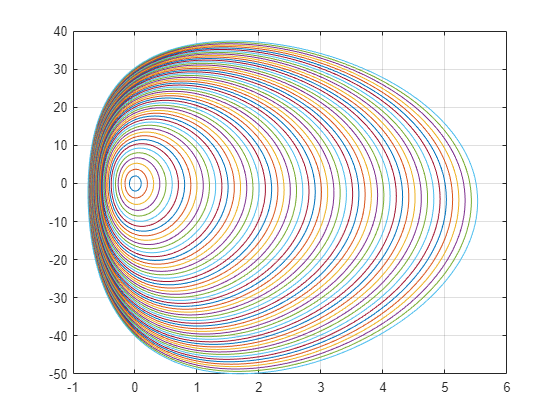

% Starting values of x
values=setdiff(0.1:0.1:5.5,0);

x2=zeros(size(values));
T=zeros(size(values));
xdif=zeros(size(values));

for i=1:size(values,2)
    x=[]; x(1) = values(i);
    y=[]; y(1) = 0;
    [T(i),x,y] = ode45cycles(0,x(1),0,0.000000001,1);
    x2(i)=values(i);
    z = findZero(x,y);
    xdif(i)=z(end)-z(1);
    plot(x,y);
    hold on
end
grid on
hold off

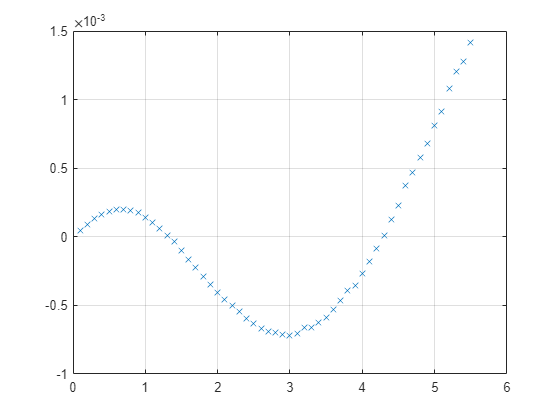

plot(x2,xdif,"x");
grid on

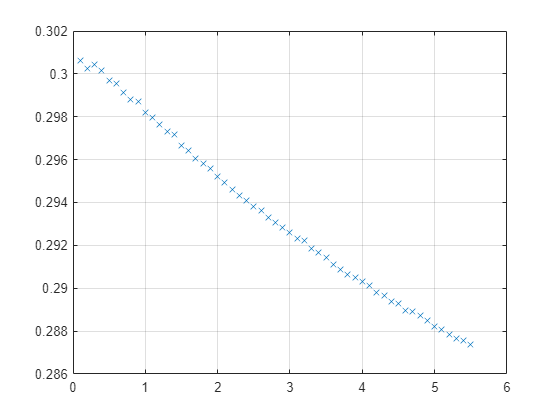

plot(x2,T,"x");
grid on

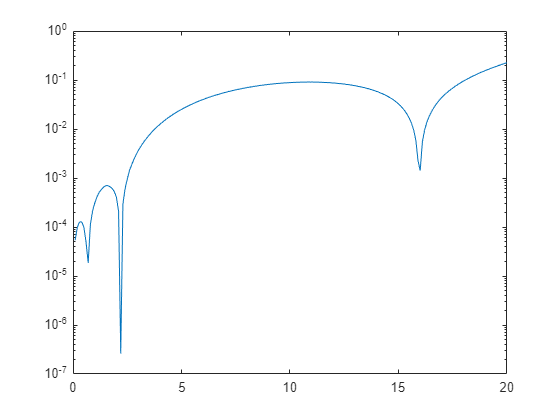

semilogy(x2,abs(xdif))

valuesa=setdiff(-4000:10:-3000,0);

xa=zeros(size(valuesa));
Ta=zeros(size(valuesa));
xdifa=zeros(size(valuesa));

for i=1:size(valuesa,2)
    xa=[]; xa(1) = valuesa(i);
    ya=[]; ya(1) = 0;
    [Ta(i),xa,ya] = ode45cycles(0,xa(1),0,0.000000001,1);
    x2a(i)=valuesa(i);
    za = findZero(xa,ya);
    xdifa(i)=za(end)-za(1);
    plot(xa,ya);
    hold on
end
grid on
hold off
plot(x2a,xdifa,"x");
grid on
plot(x2a,Ta,"x");
grid on

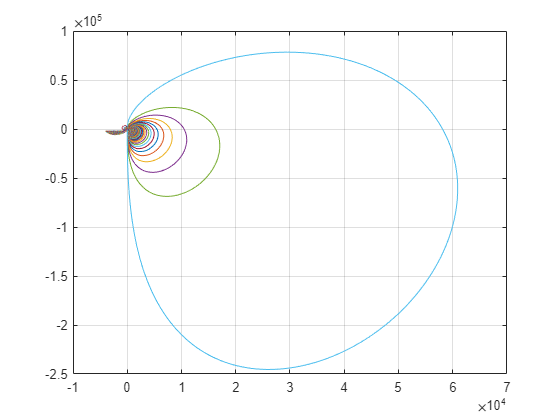

values_b=setdiff(-3000:10:-500,0);

x2_b=zeros(size(values_b));
T_b=zeros(size(values_b));
xdif_b=zeros(size(values_b));

for i=1:size(values_b,2)
    x_b=[]; x_b(1) = values_b(i);
    y_b=[]; y_b(1) = -2000;
    [T_b(i),x_b,y_b] = ode45cycles(0,x_b(1),y_b(1),0.000000001,1);
    x2_b(i)=values_b(i);
    z_b = findZero(x_b,y_b);
    xdif_b(i)=z_b(end)-z_b(1);
    plot(x_b,y_b);
    hold on
end
grid on
hold off

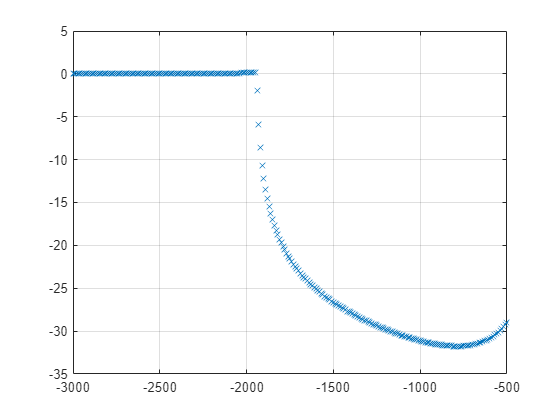

plot(x2_b,xdif_b,"x");
grid on

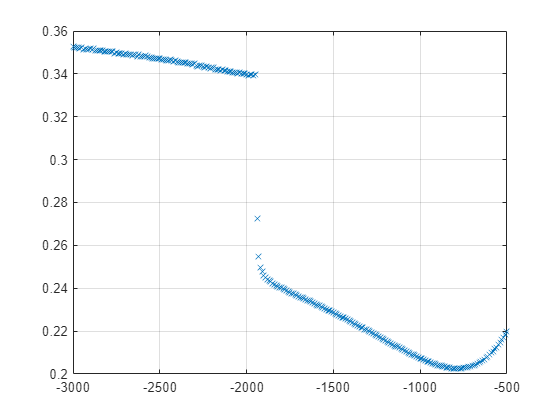

plot(x2_b,T_b,"x");
grid on

function f=fPlotTrajectory(X ,Y, Color1, Color2, Color3)
    lenTr=length(X); lenTr3=round(lenTr /9);
    lenColor1=round(4* lenTr3); lenColor2=round(7* lenTr3);
    
    plot(X(1 : lenColor1), Y(1 : lenColor1), Color1); hold on;
    plot(X(lenColor1 : lenColor2), Y(lenColor1 : lenColor2), Color2);
    hold on;
    plot(X(lenColor2 : length(X)), Y(lenColor2 : length(Y)), Color3);
end

function dz=odefcn(t, z) %
    global a1 b1 c1 al1 bt1 a2 b2 c2 al2 bt2
    dz=zeros(2,1); % z=(z(1) ,z(2))=(x,y)
    
    dz(1)=(a1 * z(1)^2+ b1 * z(1)* z(2)+ c1 * z(2)^2+ al1 * z(1)+ bt1 * z(2));
    dz(2)=(a2 * z(1)^2+ b2 * z(1)* z(2)+ c2 * z(2)^2+ al2 * z(1)+ bt2 * z(2));
end

function [Te,x,y]=ode45cycles(ti,x0,y0,acc,n)
    options=odeset('RelTol', acc ,'AbsTol', acc, 'InitialStep', acc, 'NormControl','on');
    tf=ti+10;
    k=1+2*n;
    [T, XY]= ode45(@(T,XY) odefcn(T,XY), [ti tf], [x0 y0], options);
    y_sign_change = find(XY(1:end-1 ,2).*XY(2:end,2)<=0);
    count=0;cmax=2;

    while size(y_sign_change,1)<k && count<cmax
        count=count+1;
        [T, XY]= ode45(@(T,XY) odefcn(T,XY), [ti tf], [x0 y0], options);
        tf=tf+100;
        y_sign_change = find(XY(1:end-1 ,2).*XY(2:end,2)<=0);
    end

    if(count==cmax)
%         ci=y_sign_change(2)+1;
%         T=T(1:ci);
%         XY=XY(1:ci,:);
    else
        ci=y_sign_change(k)+1;
    
        T=T(1:ci);
        XY=XY(1:ci,:);
    end
    x=XY(:,1);
    y=XY(:,2);
    Te = T(end);
end

function x0 = findZero(x,y)

    zci = @(v) find(v(:).*circshift(v(:), [-1 0]) <= 0);                    % Returns Approximate Zero-Crossing Indices Of Argument Vector
    dy = zci(y);                                                            % Indices of Approximate Zero-Crossings
    for k1 = 1:size(dy,1)-1
        b = [[1;1] [x(dy(k1)); x(dy(k1)+1)]]\[y(dy(k1)); y(dy(k1)+1)];      % Linear Fit Near Zero-Crossings
        x0(k1) = -b(1)/b(2);                                                % Interpolate ‘Exact’ Zero Crossing
        mb(:,k1) = b;                                                       % Store Parameter Estimates (Optional)
    end
end